clear; clc; close all;

%% 1. 参数设置
% 文件与数据参数
excelFile    = 'E:\FILE2\sheffeild\毕设\Data1.xlsx'; % Excel文件路径
startRow     = 2001;
windowSize   = 500;
stepSize     = 250;
selectedCols = [4,5,6,8,9,10];

% 训练参数
trainRatio = 0.7;
valRatio   = 0.15;
maxEpochs  = 50;
miniBatchSize = 64;

% 输出文件
outputModelFile = 'motor_cnn_model7.mat';

%% 2. 数据准备：先聚合所有原始数据
fprintf('步骤1: 聚合所有工作表的原始数据...\n');

步骤1: 聚合所有工作表的原始数据...


sheets = sheetnames(excelFile);
allRawFeatures = [];
allLabelsRaw = {}; % 使用Cell数组存储标签

% 遍历所有工作表，仅提取原始特征和对应标签
for sheetIdx = 1:numel(sheets)
    sheetName = sheets{sheetIdx};
    fprintf('  正在读取工作表: %s\n', sheetName);
    
    data = readtable(excelFile, 'Sheet', sheetName, 'VariableNamingRule', 'preserve');
    if size(data, 1) > startRow
        data = data(startRow:end, :);
    end
    
    if size(data, 2) >= max(selectedCols)
        featuresRaw = table2array(data(:, selectedCols));
        allRawFeatures = [allRawFeatures; featuresRaw]; % 垂直拼接所有原始特征
        
        % 根据工作表名称确定标签
        if contains(sheetName, 'Healthy', 'IgnoreCase', true)
            label = "Healthy";
        else
            label = "Faulty";
        end
        % 为当前工作表的每一行数据点关联标签
        allLabelsRaw(end+1:end+size(featuresRaw,1), 1) = {label};
    else
        warning('工作表 %s 列数不足，已跳过', sheetName);
    end
end

  正在读取工作表: Healthy_Full_Load
  正在读取工作表: Faulty_1BB_Full_Load
  正在读取工作表: Faulty_1&2BB_Full_Load
  正在读取工作表: Faulty_1&4BB_Full_Load
  正在读取工作表: Faulty_1&7BB_Full_Load
  正在读取工作表: Healthy_Load72%
  正在读取工作表: Healthy_Load81%
  正在读取工作表: Healthy_Load90%


fprintf('所有原始数据聚合完毕，总行数: %d\n', size(allRawFeatures, 1));

所有原始数据聚合完毕，总行数: 520008



%% 3. 计算并应用全局归一化参数
fprintf('步骤2: 计算并应用全局归一化参数...\n');

步骤2: 计算并应用全局归一化参数...


% 计算全局均值和标准差
global_mean = mean(allRawFeatures, 1);
global_std  = std(allRawFeatures, 0, 1);

% 检查std是否有0值，防止除零错误
global_std(global_std == 0) = 1e-6;

% 使用全局参数对所有数据进行归一化
featuresNormalized = (allRawFeatures - global_mean) ./ global_std;
fprintf('  全局均值: %s\n', mat2str(global_mean, 4));

  全局均值: [1.838e-09 6.16e-09 1.265e-10 0.004682 -0.003946 -0.0007365]


fprintf('  全局标准差: %s\n', mat2str(global_std, 4));

  全局标准差: [4.934e-05 4.921e-05 4.914e-05 5.949 5.949 5.948]



% 将归一化参数导出为txt文件，方便HLS testbench使用
writematrix(global_mean, 'global_mean.txt');
writematrix(global_std, 'global_std.txt');
fprintf('已将全局归一化参数保存到 global_mean.txt 和 global_std.txt\n');

已将全局归一化参数保存到 global_mean.txt 和 global_std.txt



%% 4. 滑动窗口处理
fprintf('步骤3: 进行滑动窗口分割...\n');

步骤3: 进行滑动窗口分割...


allData = [];
allLabels = [];
numSamples = size(featuresNormalized, 1);
numWindows = floor((numSamples - windowSize) / stepSize) + 1;

for w = 1:numWindows
    startIdx = (w-1) * stepSize + 1;
    endIdx = startIdx + windowSize - 1;
    
    windowData = featuresNormalized(startIdx:endIdx, :);
    windowData = reshape(windowData, [windowSize, size(featuresNormalized, 2), 1]);
    allData = cat(4, allData, windowData);
    
    % 从窗口中间点获取标签，更具代表性
    labelIdx = startIdx + floor(windowSize/2);
    allLabels = [allLabels; categorical(allLabelsRaw{labelIdx})];
end
allLabels = reordercats(allLabels, {'Healthy', 'Faulty'});
fprintf('滑动窗口处理完成，生成样本数: %d\n', size(allData, 4));

滑动窗口处理完成，生成样本数: 2079



%% 5. 数据划分
fprintf('步骤4: 划分数据集...\n');

步骤4: 划分数据集...


numTotalSamples = size(allData, 4);
shuffleIdx = randperm(numTotalSamples);
allData = allData(:, :, :, shuffleIdx);
allLabels = allLabels(shuffleIdx);

numTrain = floor(trainRatio * numTotalSamples);
numVal = floor(valRatio * numTotalSamples);

XTrain = allData(:, :, :, 1:numTrain);
YTrain = allLabels(1:numTrain);
XVal = allData(:, :, :, numTrain+1:numTrain+numVal);
YVal = allLabels(numTrain+1:numTrain+numVal);
XTest = allData(:, :, :, numTrain+numVal+1:end);
YTest = allLabels(numTrain+numVal+1:end);
fprintf('数据集划分: 训练=%d, 验证=%d, 测试=%d\n', numTrain, numVal, size(XTest,4));

数据集划分: 训练=1455, 验证=311, 测试=313




%% 6. 构建并训练CNN模型 (与您原脚本一致)
fprintf('步骤5: 构建并训练CNN模型...\n');

步骤5: 构建并训练CNN模型...


inputSize = [windowSize, size(featuresNormalized, 2), 1];
numClasses = numel(categories(YTrain));
classOrder = categories(YTrain);

layers = [
    imageInputLayer(inputSize, 'Name', 'input', 'Normalization', 'none') % 输入层不再做归一化
    convolution2dLayer([3, 1], 4, 'Padding', 'same', 'Name', 'conv1_time')
    batchNormalizationLayer('Name', 'bn1')
    reluLayer('Name', 'relu1')
    convolution2dLayer([1, 3], 8, 'Padding', 'same', 'Name', 'conv2_spatial')
    batchNormalizationLayer('Name', 'bn2')
    reluLayer('Name', 'relu2')
    maxPooling2dLayer([2, 1], 'Stride', [2, 1], 'Name', 'pool2')
    convolution2dLayer([3, 3], 16, 'Padding', 'same', 'Name', 'conv3_mixed')
    batchNormalizationLayer('Name', 'bn3')
    reluLayer('Name', 'relu3')
    maxPooling2dLayer([2, 2], 'Stride', [2, 2], 'Name', 'pool3') 
    globalAveragePooling2dLayer('Name', 'global_avg_pool')
    fullyConnectedLayer(numClasses, 'Name', 'fc_final')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'output', 'Classes', classOrder)
];

options = trainingOptions('adam', ...
    'MaxEpochs', maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'ValidationData', {XVal, YVal}, ...
    'Plots', 'training-progress', ...
    'Verbose', true, ...
    'Shuffle', 'every-epoch');

在单 GPU 上训练。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量准确度　　｜　　验证准确度　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０５　｜　　　２３．４４％　｜　　６８．４９％　｜　　０．７１１０　｜　０．６７９４　｜　　０．００１０　｜
｜　　　３　｜　　　５０　｜　　　　　００：００：０７　｜　　　８９．０６％　｜　　９０．６８％　｜　　０．４０６８　｜　０．３５２２　｜　　０．００１０　｜
｜　　　５　｜　　１００　｜　　　　　００：００：０８　｜　　　８４．３８％　｜　　９０．６８％　｜　　０．３５２７　｜　０．２８４４　｜　　０．００１０　｜
｜　　　７　｜　　１５０　｜　　　　　００：００：０９　｜　　　９８．４４％　｜　　９３．２５％　｜　　０．１８６２　｜　０．２４７３　｜　　０．００１０　｜
｜　　１０　｜　　２００　｜　　　　　００：００：１０　｜　　　９５．３１％　｜　　９２．６０％　｜　　０．１７４２　｜　０．２１９５　｜　　０．００１０　｜
｜　　１２　｜　　２５０　｜　　　　　００：００：１１　｜　　　９３．７５％　｜　　９４．２１％　｜　　０．１７８８　｜　０．１９８６　｜　　０．００１０　｜
｜　　１４　｜　　３００　｜　　　　　００：００：１２　｜　　　９８．４４％　｜　　９１．９６％　｜　　０．１４１０　｜　０．１９２９　｜　　０．００１０　｜
｜　　１６　｜　　３５０　｜　　　　　００：００：１３　｜　　　９２．１９％　｜　　９４．８６％　｜　　０．１７１６　｜　０．１６９３　｜　　０．００１０　｜
｜　　１９　｜　　４００　｜　　　　　００：００：１４　

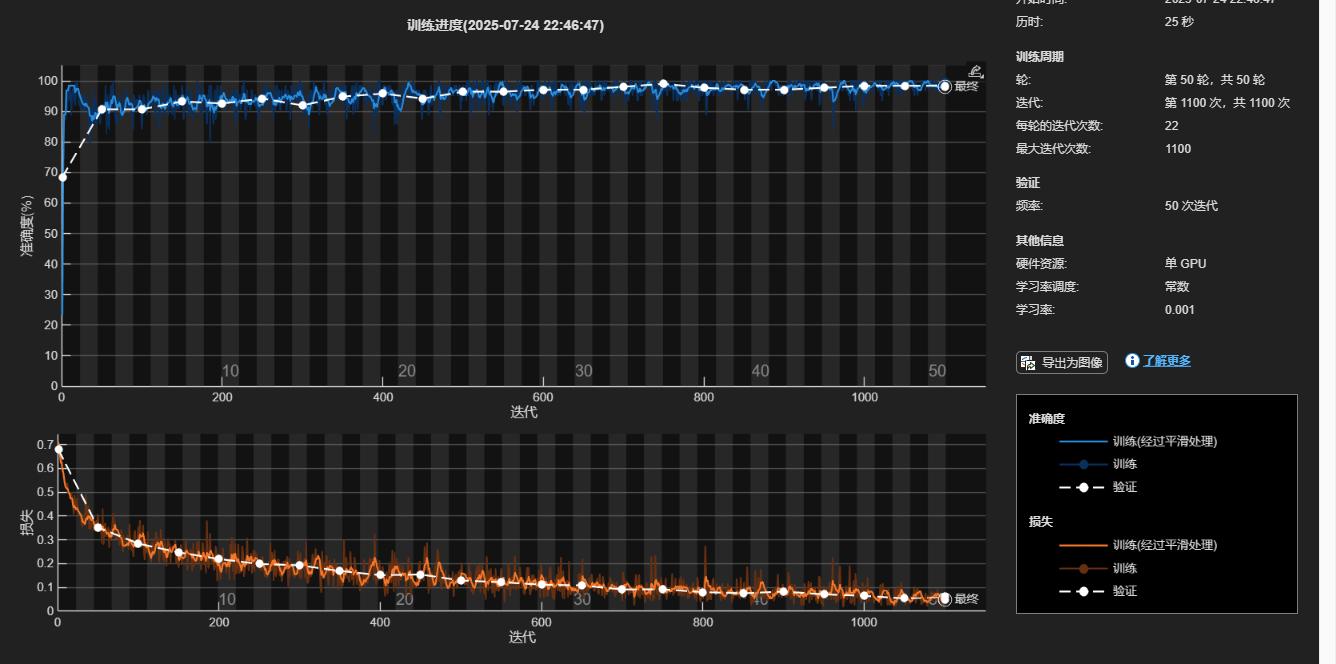


net = trainNetwork(XTrain, YTrain, layers, options);

fprintf('模型训练完成。\n');

模型训练完成。



%% 7. 评估并保存模型
fprintf('步骤6: 评估并保存模型...\n');

步骤6: 评估并保存模型...


YPred = classify(net, XTest);
accuracy = sum(YPred == YTest) / numel(YTest);
fprintf('独立测试集准确率: %.2f%%\n', accuracy * 100);

独立测试集准确率: 98.40%


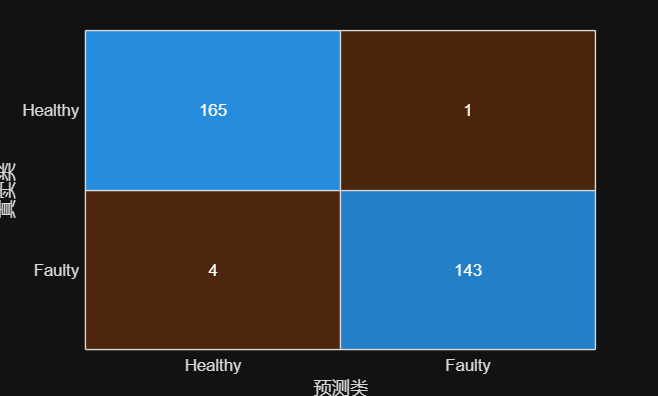


进行噪声鲁棒性测试...


函数或变量 'XTestTrain' 无法识别。

figure; confusionchart(YTest, YPred);


% 将模型和归一化参数保存在一起
modelInfo.global_mean = global_mean;
modelInfo.global_std = global_std;
modelInfo.windowSize = windowSize;
modelInfo.stepSize = stepSize;
modelInfo.classNames = classOrder;

save(outputModelFile, 'net', 'modelInfo');
fprintf('模型及归一化参数已保存到: %s\n', outputModelFile);